# Main Script

% Objectives
% Run to Test the whole Algorithm
% Creates directories if not present
createDir()
% Asks user to select ZIP File and unloads the images 
% Only asks for Zip if there are no images in DICOMImgs
if numel(dir('DICOMImgs')) == 2
    unzipImages()
end
if numel(dir('Reports')) == 2
    unzipReports() 
end
% Loading DICOMCollection
%% Only imports collection if the collection variable is not present
if exist("collection","var") == 0
    %% update current collection by running dCollection.mlx 
    % or loading from t2_collection.mat if available
    if exist('collection.mat','file')
        load('collection.mat')
        load('t2_collection.mat')
    else 
        run('dCollection.mlx')
        save('collection.mat','collection','-mat')
    end
end
if height(collection) == 0
    fprintf('No files in collection.')
    error('No Files In Collection')
end


## TPM Reports and Filtering Collection

%TPMReports gets TPM information for only patients in dicomcollection
% It also filters collection to appropiate patients. 
[selectedTPM,filteredCollection] = TPMReports(collection)

cPI = 23×1 table
    uniquePatientNames
    __________________

       "P-10650700"   
       "P-10861325"   
       "P-11358796"   
       "P-11441271"   
       "P-11691004"   
       "P-11691939"   
       "P-11957282"   
       "P-11966795"   
       "P-11994173"   
       "P-12099863"   
       "P-12268789"   
       "P-12408722"   
       "P-12429972"   
       "P-12620723"   
       "P-12720015"   
       "P-12734582"   


filepath = 'Reports/OA_575 complete patients/OA_575 complete patients/TPM Data/PROMIS_OA_TPMSummary_Downloaded05Mar2020.xlsx'

Variables:

    Trial: 575×1 cell array of character vectors

    patientID: 575×1 cell array of character vectors

    VisitCycle: 575×1 double

        Values:

            Min          1    
            Median       1    
            Max          1    

    FormCycle: 575×1 double

        Values:

            Min          1    
            Median       1    
            Max          1    

    RepeatNumber: 575×1 double

        Values:

            Min          1    
            Median       1    
            Max          1    

    sumca1: 575×1 double

        Values:

            Min          0    
            Median       1    
            Max          1    

    sumccluk: 575×1 double

        Values:

            Min             1     
            Median          6     
            Max             17    
            NumMissing      168   

    sumcc1

selectedTPM = 23×13 table
                    patientID       sumca1    sumccluk    sumcc1    sumal1    sumal2    summa1    summa2    sumpe1    sumlvinv    sumsevin    sumhgpin    sumasap
                  ______________    ______    ________    ______    ______    ______    ______    ______    ______    ________    ________    ________    _______

    P-10650700    {'P-10650700'}      1           6          6         4         3         4         3         0          0         NaN         NaN         NaN  
    P-10861325

filteredCollection = 60×12 table
            PatientName     PatientSex    Modality    Rows    Columns    Channels    Frames    StudyDescription         SeriesDescription                                   StudyInstanceUID                                                     SeriesInstanceUID                               Filenames  
            ____________    __________    ________    ____    _______    ________    ______    ________________    ____________________________    __________________________________________________________________    __________________________________________________________________<


% Saving images to labeled files to be converted into image data store
% labelImages should run here 
if numel(dir('LabeledImgs/cancerImgs')) == 2 
    labelImages(filteredCollection,selectedTPM)
    
end
save('afterLabel','-mat')


Saving to: /home/madelaine/Documents/SHUDocs/ProstateResearch/promis_open/scriptsFinal/matlab.mat



% Save imges to image data store

% Uses the folder names to label images 
% then make an image datastore and save it to imds 
imds = makeimds();

Loaded ImageDataStore

## Image Training

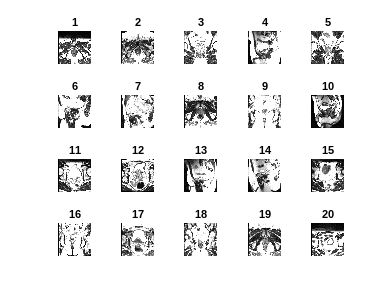


displaySample(imds)

### Label Count And Histogram 

figure;
countEachLabel(imds)

ans = 2×2 table
       Label        Count
    ____________    _____

    cancerImgs       875 
    nocancerImgs     557 


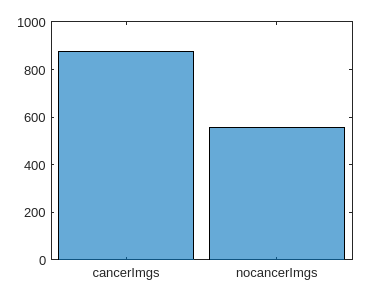

histogram (imds.Labels)

## Divide Data into Train, Validation and Testing Datasets 

 numTrainFiles = 400;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomized');

### Simple vs  Recursive DNN

inputSize = [256 256 1];
numClasses = 2;

%simple layers 
%Simple Layers is a 
simpleLayers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

recursivelayers = [
    % Image Input layer
    imageInputLayer(inputSize)
    % Convolutional Layer
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer

    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

%choose which configuration you want to use here. 

fig = uifigure()

fig =   Figure with properties:

      Number: []
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1640 458 560 420]
       Units: 'pixels'

  Show all properties



decision = uiconfirm(fig,'Simple or Recursive','','Options',{'Simple','Recursive'})

decision = 'Recursive'

switch decision
    case 'Simple'
        layers = simpleLayers
    case 'Recursive'
        layers = recursivelayers
end

layers =   15×1 Layer array with layers:

     1   ''   Image Input             256×256×1 images with 'zerocenter' normalization
     2   ''   2-D Convolution         8 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization     Batch normalization
     4   ''   ReLU                    ReLU
     5   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   ''   2-D Convolution         16 3×3 convolutions with stride [1  1] and padding 'same'
     7   ''   Batch Normalization     Batch normalization
     8   ''   ReLU                    ReLU
     9   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding 'same'
    11   ''   Batch Normalization     Batch normalization
    12   ''   ReLU                    ReLU
    13  

delete(fig)


Training Options

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

Training Command 

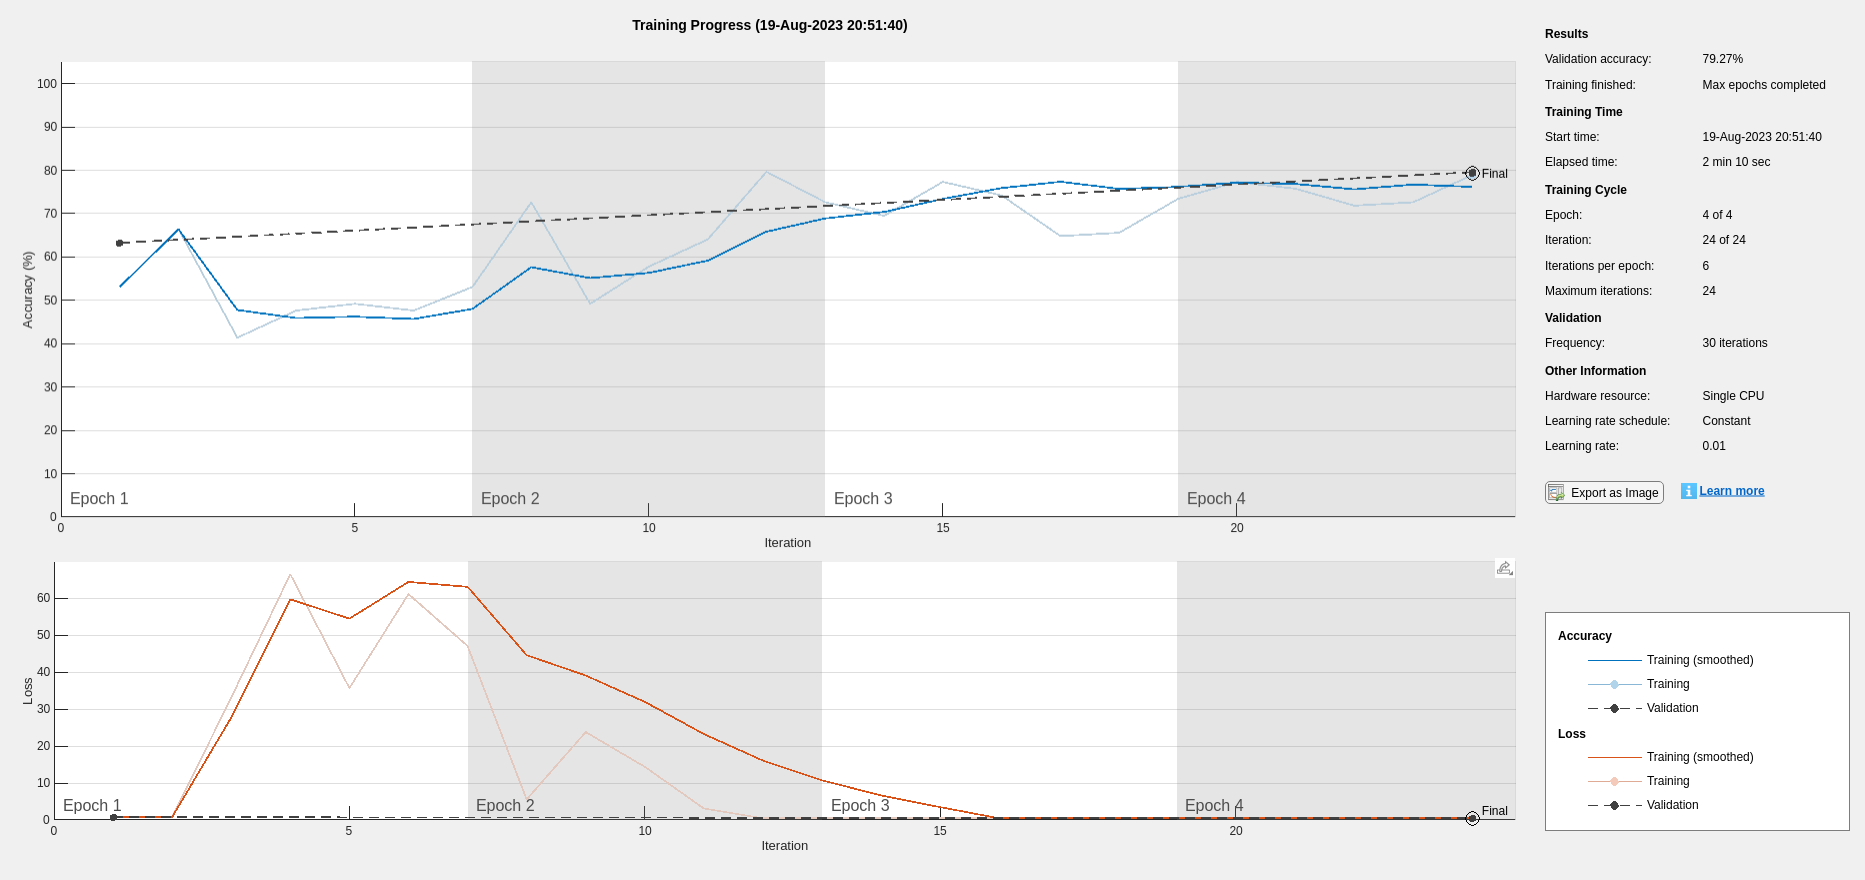

net = trainNetwork(imdsTrain,layers,options);

% Use the algorithm to classify Validation DataSet
YPred = classify(net,imdsValidation)

YPred = 632×1 categorical array
     cancerImgs 
     cancerImgs 
     nocancerImgs 
     cancerImgs 
     cancerImgs 
     nocancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     nocancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 


% Sets YValidation Labels
YValidation = imdsValidation.Labels

YValidation = 632×1 categorical array
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 
     cancerImgs 


Finds the Accuracy of the algorithm by comparing with the YValidation Labels

accuracy = mean(YPred == YValidation)

accuracy = 0.7927

function displaySample(imds) 
    figure;
    title('Random Selection of Loaded Images');
    perm = randperm(1000,20);
    
    
    for i = 1:20
        subplot(4,5,i);
        img = imread(imds.Files{perm(i)});
        %  [BW,img] = segmentImage(img)
        % This doesnt work but I do need to preprocess the images before
        % analysing them. 
        imshow(img)
        title(i)
    end
end 

function createDir()
    if ~exist('DICOMImgs','dir')
        mkdir('DICOMImgs')
    end
    if ~exist('LabeledImgs','dir')
        mkdir('LabeledImgs')
    end
end
% Gets file and unzips the images to DicomImgs Folder